%% =========================================================
% Gezielte LAB-Analyse problematischer blauer Schildbilder
%
% In jedem Bild werden zunächst die einzelnen Bedingungen
% dargestellt. Anschließend werden echte blaue Schildpixel
% manuell angeklickt und ohne Vorfilterung analysiert.
% ==========================================================

clear;
clc;
close all;


%% 1. Ordner der Problembilder

problemFolder = ...
    "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung";


%% 2. Aktuell verwendete grobe Blau-Schwelle

% Aufbau:
% [L_min, L_max, a_min, a_max, b_min, b_max]

blueThreshold = [
     0, 100, ...
   -30,  25, ...
  -128,   0
];


%% 3. Ausgabedatei

outputCsv = fullfile( ...
    problemFolder, ...
    "LAB_Analyse_Problembilder_Blau.csv");


%% 4. Bilder erfassen

imds = imageDatastore( ...
    problemFolder, ...
    "IncludeSubfolders", true);

numberOfImages = numel(imds.Files);

if numberOfImages == 0
    error("Im Problemordner wurden keine Bilder gefunden.");
end


%% 5. Grenzwerte auslesen

Lmin = blueThreshold(1);
Lmax = blueThreshold(2);

Amin = blueThreshold(3);
Amax = blueThreshold(4);

Bmin = blueThreshold(5);
Bmax = blueThreshold(6);


%% 6. Ergebnistabelle vorbereiten

allResults = table();


%% 7. Problembilder einzeln analysieren

for i = 1:numberOfImages

    %% Bild laden

    I = imread(imds.Files{i});

    % Graubild gegebenenfalls in RGB umwandeln
    if ndims(I) == 2 || size(I,3) == 1
        I = repmat(I, 1, 1, 3);
    end

    % Eventuellen Alphakanal entfernen
    if size(I,3) > 3
        I = I(:,:,1:3);
    end


    %% RGB nach LAB umwandeln

    labImage = rgb2lab(I);

    L = labImage(:,:,1);
    A = labImage(:,:,2);
    B = labImage(:,:,3);


    %% Einzelne Bedingungen berechnen

    maskL = ...
        L >= Lmin & ...
        L <= Lmax;

    maskA = ...
        A >= Amin & ...
        A <= Amax;

    maskB = ...
        B >= Bmin & ...
        B <= Bmax;

    combinedMask = maskL & maskA & maskB;


    %% Debug-Ansicht

    debugFigure = figure( ...
        "Name", ...
        "Problembild " + i + " von " + numberOfImages, ...
        "NumberTitle", "off");

    tiledlayout( ...
        2, 4, ...
        "TileSpacing", "compact", ...
        "Padding", "compact");


    nexttile;
    imshow(I);
    title("Original");


    nexttile;
    imshow(L, []);
    title("L*-Kanal");


    nexttile;
    imshow(maskL);
    title("L*-Bedingung");


    nexttile;
    imshow(maskA);
    title("a*-Bedingung");


    nexttile;
    imshow(maskB);
    title("b*-Bedingung");


    nexttile;
    imshow(combinedMask);
    title("Gemeinsame Maske");


    nexttile;

    overlayImage = labeloverlay( ...
        I, ...
        combinedMask, ...
        "Transparency", 0.55);

    imshow(overlayImage);
    title("Erkannte Pixel");


    nexttile;
    imshow(I);
    title("Bildübersicht");


    sgtitle( ...
        "Blauanalyse | Bild " + i + ...
        " von " + numberOfImages, ...
        "Interpreter", "none");


    %% Tatsächliche blaue Schildpixel anklicken

    selectionFigure = figure( ...
        "Name", "Blaue Pixel auswählen", ...
        "NumberTitle", "off");

    imshow(I);

    title({ ...
        "Klicke auf tatsächlich blaue Schildpixel", ...
        "Drücke ENTER, wenn alle gewünschten Pixel markiert sind" ...
    });

    fprintf("\n============================================\n");
    fprintf("Bild %d von %d\n", i, numberOfImages);
    fprintf("%s\n", imds.Files{i});
    fprintf("Blaue Schildpixel anklicken.\n");
    fprintf("Mit ENTER wird die Auswahl beendet.\n");

    [x, y] = ginput;


    %% Keine Punkte ausgewählt

    if isempty(x)

        fprintf("Keine Pixel ausgewählt. Bild wird übersprungen.\n");

        close(selectionFigure);

        fprintf("Taste drücken für das nächste Bild.\n");
        waitforbuttonpress;

        if isvalid(debugFigure)
            close(debugFigure);
        end

        continue;

    end


    %% Koordinaten auf gültige Pixelpositionen begrenzen

    x = round(x);
    y = round(y);

    x = max(1, min(size(I,2), x));
    y = max(1, min(size(I,1), y));


    %% LAB-Werte der angeklickten Pixel auslesen

    linearIndices = sub2ind( ...
        size(L), ...
        y, ...
        x);

    selectedL = L(linearIndices);
    selectedA = A(linearIndices);
    selectedB = B(linearIndices);


    %% Für jeden Punkt prüfen, welche Bedingungen erfüllt sind

    passL = ...
        selectedL >= Lmin & ...
        selectedL <= Lmax;

    passA = ...
        selectedA >= Amin & ...
        selectedA <= Amax;

    passB = ...
        selectedB >= Bmin & ...
        selectedB <= Bmax;

    passAll = passL & passA & passB;


    %% Tabelle für das aktuelle Bild erzeugen

    numberOfPoints = numel(x);

    fileColumn = repmat( ...
        imds.Files(i), ...
        numberOfPoints, ...
        1);

    imageNumberColumn = repmat( ...
        i, ...
        numberOfPoints, ...
        1);

    currentResults = table( ...
        fileColumn, ...
        imageNumberColumn, ...
        x, ...
        y, ...
        selectedL, ...
        selectedA, ...
        selectedB, ...
        passL, ...
        passA, ...
        passB, ...
        passAll, ...
        'VariableNames', ...
        { ...
            'Datei', ...
            'Bildnummer', ...
            'X', ...
            'Y', ...
            'L_Wert', ...
            'A_Wert', ...
            'B_Wert', ...
            'L_Bedingung', ...
            'A_Bedingung', ...
            'B_Bedingung', ...
            'Gesamtbedingung' ...
        });


    %% Mit bisherigen Ergebnissen verbinden

    if isempty(allResults)

        allResults = currentResults;

    else

        allResults = [
            allResults;
            currentResults
        ];

    end


    %% Ergebnisse des aktuellen Bildes ausgeben

    fprintf("\nAusgewählte Pixel: %d\n", numberOfPoints);

    fprintf( ...
        "L*-Bedingung erfüllt: %.1f %%\n", ...
        100 * mean(passL));

    fprintf( ...
        "a*-Bedingung erfüllt: %.1f %%\n", ...
        100 * mean(passA));

    fprintf( ...
        "b*-Bedingung erfüllt: %.1f %%\n", ...
        100 * mean(passB));

    fprintf( ...
        "Alle Bedingungen erfüllt: %.1f %%\n\n", ...
        100 * mean(passAll));


    %% Perzentile der angeklickten Pixel bestimmen

    percentileValues = [2; 5; 50; 95; 98];

    selectedValues = [
        selectedL, ...
        selectedA, ...
        selectedB
    ];

    percentileResults = prctile( ...
        selectedValues, ...
        percentileValues, ...
        1);

    percentileTable = table( ...
        percentileValues, ...
        percentileResults(:,1), ...
        percentileResults(:,2), ...
        percentileResults(:,3), ...
        'VariableNames', ...
        {'Perzentil', 'L_Wert', 'A_Wert', 'B_Wert'});

    fprintf("Perzentile der tatsächlich angeklickten blauen Pixel:\n");
    disp(percentileTable);


    %% Ange­klickte Pixel im a*-b*-Raum darstellen

    scatterFigure = figure( ...
        "Name", "LAB-Werte der ausgewählten Pixel", ...
        "NumberTitle", "off");

    scatter( ...
        selectedA, ...
        selectedB, ...
        45, ...
        selectedL, ...
        "filled");

    hold on;


    % Aktuelles Schwellenrechteck einzeichnen
    rectangle( ...
        "Position", ...
        [ ...
            Amin, ...
            Bmin, ...
            Amax - Amin, ...
            Bmax - Bmin ...
        ], ...
        "LineWidth", 2, ...
        "LineStyle", "--");


    xlabel("a* – Grün bis Rot");
    ylabel("b* – Blau bis Gelb");

    title({ ...
        "Angeklickte blaue Schildpixel", ...
        "Rechteck = aktuell verwendeter a*-b*-Bereich" ...
    });

    colorbar;
    grid on;

    hold off;


    %% Zum nächsten Bild wechseln

    fprintf("Taste oder Mausklick zum nächsten Bild.\n");

    waitforbuttonpress;

    if isvalid(debugFigure)
        close(debugFigure);
    end

    if isvalid(selectionFigure)
        close(selectionFigure);
    end

    if isvalid(scatterFigure)
        close(scatterFigure);
    end

end

Bild 1 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0019_Geschwindigkeitsempfehlung_30_1092.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 14


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 21.4 %


Alle Bedingungen erfüllt: 21.4 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert     A_Wert     B_Wert 
    _________    ______    ________    _______

        2        10.826     -5.6245    -3.4208
        5        10.874     -5.5018    -3.2811
       50        12.276     -2.1345     1.0142
       95        15.536    -0.61868     6.5332
       98        15.744    -0.48734     7.2372



Taste oder Mausklick zum nächsten Bild.


Bild 2 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0020_Geschwindigkeitsempfehlung_30_1097.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 14


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 21.4 %


Alle Bedingungen erfüllt: 21.4 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        9.1264    -6.4909    -1.6615
        5        9.5656    -6.1438    -1.6602
       50        14.692    -1.6449      1.334
       95        26.546     1.6553     9.1141
       98        27.735     1.6566     9.4899



Taste oder Mausklick zum nächsten Bild.


Bild 3 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0024_Geschwindigkeitsempfehlung_30_1136.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 15


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 33.3 %


Alle Bedingungen erfüllt: 33.3 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert     A_Wert     B_Wert 
    _________    ______    ________    _______

        2        9.8403      -6.231    -6.6296
        5        9.8403     -6.1759    -6.6296
       50        12.088    -0.54972    0.93193
       95        31.211      3.2592     12.164
       98        33.568      3.7636     12.569



Taste oder Mausklick zum nächsten Bild.


Bild 4 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0026_Geschwindigkeitsempfehlung_30_1141.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 16


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 25.0 %


Alle Bedingungen erfüllt: 25.0 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        8.8347    -6.4426    -8.1808
        5        9.0451    -6.1464    -7.7333
       50        11.742    -2.7179     1.8375
       95        18.958     2.8287     9.0272
       98        19.955     3.4827     10.622



Taste oder Mausklick zum nächsten Bild.


Bild 5 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0058_Geschwindigkeitsempfehlung_30_1360.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 15


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 66.7 %


Alle Bedingungen erfüllt: 66.7 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        5.4073     -7.681    -12.301
        5        5.9009    -7.6163    -10.529
       50        8.8951    -1.5676    -1.3389
       95        12.188    0.35956     5.8447
       98        12.287    0.46949     6.8048



Taste oder Mausklick zum nächsten Bild.


Bild 6 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0060_Geschwindigkeitsempfehlung_30_1373.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 16


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 87.5 %


Alle Bedingungen erfüllt: 87.5 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        6.7825    -5.0111    -12.539
        5        6.8244    -4.3245    -12.253
       50        9.7468    0.74835    -6.0227
       95        19.953     4.6454     5.4686
       98        21.373     4.6692     6.2192



Taste oder Mausklick zum nächsten Bild.


Bild 7 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0067_Geschwindigkeitsempfehlung_30_1411.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 10


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 60.0 %


Alle Bedingungen erfüllt: 60.0 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        8.1886    -8.8244     -7.968
        5        8.1886    -8.8244     -7.968
       50        10.385    -3.0231    -1.7037
       95        22.135     1.1678     7.7265
       98        22.135     1.1678     7.7265



Taste oder Mausklick zum nächsten Bild.


Bild 8 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0075_Verkehrsberuhigter_Bereich-2025-06-19__12_Viereck_02.png


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 23


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 47.8 %


Alle Bedingungen erfüllt: 47.8 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        6.7014    -11.272    -6.9501
        5         6.846    -11.093     -4.824
       50        10.165    -4.8745    0.71097
       95        12.771    -1.0178     6.3944
       98        12.998    -1.0169     7.0874



Taste oder Mausklick zum nächsten Bild.


Bild 9 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0079_Geschwindigkeitsempfehlung_30_1474.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 15


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 53.3 %


Alle Bedingungen erfüllt: 53.3 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        7.1537    -8.3644    -6.6297
        5        8.0108    -8.0845    -5.8508
       50        12.932    -2.5827    -2.5172
       95        16.113     3.3184     8.0318
       98        16.846     4.1369     8.0937



Taste oder Mausklick zum nächsten Bild.


Bild 10 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0080_Geschwindigkeitsempfehlung_30_1477.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 17


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 35.3 %


Alle Bedingungen erfüllt: 35.3 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        8.9432    -7.0968    -7.2359
        5        9.1459     -6.326    -6.5945
       50        13.198    -1.5811     1.2887
       95        32.383     3.3976     9.7516
       98        39.104     4.0536     10.251



Taste oder Mausklick zum nächsten Bild.


Bild 11 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0082_Geschwindigkeitsempfehlung_30_1480.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 10


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 20.0 %


Alle Bedingungen erfüllt: 20.0 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert
    _________    ______    _______    ______

        2        9.3238     -5.644    -4.644
        5        9.3238     -5.644    -4.644
       50        13.202    -3.1536    4.4936
       95        23.395     3.1681    8.0119
       98        23.395     3.1681    8.0119



Taste oder Mausklick zum nächsten Bild.


Bild 12 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0084_Verkehrsberuhigter_Bereich-2025-06-19__20_Viereck_01.png


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 28


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 75.0 %


Alle Bedingungen erfüllt: 75.0 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        5.7711    -8.0562    -9.0034
        5        6.0896    -7.9588    -7.0943
       50        9.6867    -3.0164    -2.5875
       95         12.18     1.4325     3.5317
       98        15.108     3.6171     4.9361



Taste oder Mausklick zum nächsten Bild.


Bild 13 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0085_Geschwindigkeitsempfehlung_30_1517.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 21


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 81.0 %


Alle Bedingungen erfüllt: 81.0 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        7.6581    -4.8765    -9.9173
        5         7.966    -4.1799    -8.4425
       50        10.372    -1.7365    -1.8408
       95        14.095     3.6661      3.106
       98        14.748     4.0536     3.5976



Taste oder Mausklick zum nächsten Bild.


Bild 14 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0085_Verkehrsberuhigter_Bereich-2025-06-19__21_Viereck_03.png


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 25


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 40.0 %


Alle Bedingungen erfüllt: 40.0 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert     A_Wert     B_Wert 
    _________    ______    ________    _______

        2        5.1459      -7.604    -7.8335
        5        5.5906     -6.8531    -5.4587
       50        8.1132     -4.1533     1.0733
       95        15.244    -0.90664     6.6568
       98        20.438     -0.8824     8.9672



Taste oder Mausklick zum nächsten Bild.


Bild 15 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0088_Verkehrsberuhigter_Bereich-2025-06-19__24_Viereck_03.png


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 48


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 52.1 %


Alle Bedingungen erfüllt: 52.1 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        4.9715    -9.5557     -8.939
        5        5.9685    -8.0899     -8.048
       50        10.076    -3.1872    -0.6161
       95         14.47     1.2157      8.271
       98        14.823      3.094     8.9151



Taste oder Mausklick zum nächsten Bild.


Bild 16 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0100_Geschwindigkeitsempfehlung_30_1607.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 16


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 18.8 %


Alle Bedingungen erfüllt: 18.8 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        5.0414    -8.6282    -6.5506
        5        5.3992    -8.5821    -5.7359
       50        13.602    -3.5624     3.8074
       95        19.047     2.4639     9.7322
       98        19.318       2.66        9.9



Taste oder Mausklick zum nächsten Bild.


Bild 17 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0104_Verkehrsberuhigter_Bereich-2025-06-19__43_Viereck_02.png


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 47


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 59.6 %


Alle Bedingungen erfüllt: 59.6 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        4.7258    -9.7292    -9.0407
        5        7.6059    -8.6841    -7.8274
       50        10.885    -3.0366     -2.583
       95        19.165     1.0396      4.968
       98        23.486     3.2601     10.144



Taste oder Mausklick zum nächsten Bild.


Bild 18 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0107_Geschwindigkeitsempfehlung_30_1664.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 25


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 8.0 %


Alle Bedingungen erfüllt: 8.0 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        5.6331     -6.545    -8.2383
        5        5.6721    -6.4241    -5.6511
       50        12.487    -2.5346     3.2016
       95        19.521    0.27588     8.9702
       98         19.54     2.4957     10.734



Taste oder Mausklick zum nächsten Bild.


Bild 19 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0114_Verkehrsberuhigter_Bereich-2025-06-19__54_Viereck_02.png


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 41


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 68.3 %


Alle Bedingungen erfüllt: 68.3 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        7.0424    -9.0676    -6.1759
        5        7.5122    -8.3229    -6.0933
       50        10.569    -3.0096    -1.3068
       95        16.974     0.5259     7.6454
       98        17.979     1.3862     9.6458



Taste oder Mausklick zum nächsten Bild.


Bild 20 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0116_Verkehrsberuhigter_Bereich-2025-06-19__56_Viereck_03.png


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 22


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 95.5 %


Alle Bedingungen erfüllt: 95.5 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert      B_Wert 
    _________    ______    _______    ________

        2        6.3807    -5.3611     -13.784
        5        6.5547    -5.2924     -11.021
       50        8.2245    -1.0793     -5.0653
       95        10.711      2.093    -0.75297
       98        10.711     3.4262     0.67034



Taste oder Mausklick zum nächsten Bild.


Bild 21 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0126_Verkehrsberuhigter_Bereich-2025-06-19__67_Viereck_03.png


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 22


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 63.6 %


Alle Bedingungen erfüllt: 63.6 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        7.0556    -10.065    -10.397
        5        7.5737    -9.3156    -9.6362
       50         10.32    -2.8718    -2.9058
       95        13.476     3.2403      6.748
       98        14.486     3.6255     10.881



Taste oder Mausklick zum nächsten Bild.


Bild 22 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0130_Verkehrsberuhigter_Bereich-2025-06-19__70_Viereck_01.png


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 24


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 83.3 %


Alle Bedingungen erfüllt: 83.3 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        6.4561    -11.064    -10.298
        5        6.9515     -9.264    -10.298
       50        10.582     -1.146    -2.6242
       95        16.189     2.1909     7.0256
       98         18.54     2.2179     7.6321



Taste oder Mausklick zum nächsten Bild.


Bild 23 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0133_Verkehrsberuhigter_Bereich-2025-06-19__74_Viereck_02.png


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 28


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 50.0 %


Alle Bedingungen erfüllt: 50.0 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert      B_Wert 
    _________    ______    _______    ________

        2        6.0298    -8.4265     -7.8777
        5        6.8495    -8.3582     -7.8777
       50        11.289    -3.5002    0.026861
       95        22.513      2.529      13.695
       98        30.653     4.5149      13.765



Taste oder Mausklick zum nächsten Bild.


Bild 24 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0134_Verkehrsberuhigter_Bereich-2025-06-19__75_Viereck_04.png


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 30


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 80.0 %


Alle Bedingungen erfüllt: 80.0 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        2.9803    -6.3817    -7.9368
        5        3.8356    -6.1448    -7.9368
       50        7.0322    -3.5544    -2.5854
       95        20.191     1.4297     8.6462
       98        65.829     1.4297      13.94



Taste oder Mausklick zum nächsten Bild.


Bild 25 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0135_Verkehrsberuhigter_Bereich-2025-06-19__76_Viereck_03.png


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 19


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 52.6 %


Alle Bedingungen erfüllt: 52.6 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        5.4404    -7.0714    -7.8917
        5        6.0718    -6.9978    -7.8177
       50        9.7669    -1.9247          0
       95        12.968    0.29261      5.024
       98        13.063    0.48979     5.2736



Taste oder Mausklick zum nächsten Bild.


Bild 26 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0139_Verkehrsberuhigter_Bereich-2025-06-19__83_Viereck_01.png


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 14


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 71.4 %


Alle Bedingungen erfüllt: 71.4 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        7.9086    -7.3529    -9.3169
        5        7.9925    -7.2532    -8.7975
       50        9.3094    -1.0622    -3.4184
       95        13.772     2.0667     4.1629
       98        13.916     2.2532     4.6709



Taste oder Mausklick zum nächsten Bild.


Bild 27 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0143_Geschwindigkeitsempfehlung_30_1896.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 17


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 64.7 %


Alle Bedingungen erfüllt: 64.7 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert     A_Wert      B_Wert 
    _________    ______    ________    ________

        2        7.8322      -7.604     -6.8417
        5          8.15      -7.512     -6.3079
       50        11.011    0.036569    -0.33185
       95        16.926      4.7728      5.8505
       98         17.49       5.229      6.7954



Taste oder Mausklick zum nächsten Bild.


Bild 28 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0146_Geschwindigkeitsempfehlung_30_1932.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 16


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 43.8 %


Alle Bedingungen erfüllt: 43.8 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert      B_Wert 
    _________    ______    _______    ________

        2        7.7253     -5.666       -6.72
        5        7.9061    -5.0373     -6.3174
       50        11.175    -1.0122    0.050198
       95        19.089     2.5825      5.7852
       98        20.436     3.1232      6.1502



Taste oder Mausklick zum nächsten Bild.


Bild 29 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0148_Geschwindigkeitsempfehlung_30_1940.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 24


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 66.7 %


Alle Bedingungen erfüllt: 66.7 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2         7.793    -6.7149    -11.464
        5        8.2385    -6.6589    -7.9669
       50        12.387    -4.3231    -1.2408
       95        15.514     3.8181     6.8775
       98        17.235     4.9577      10.62



Taste oder Mausklick zum nächsten Bild.


Bild 30 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0150_Geschwindigkeitsempfehlung_30_1967.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 15


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 66.7 %


Alle Bedingungen erfüllt: 66.7 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        9.2453    -5.5053    -7.3114
        5        9.8855      -5.08    -6.8678
       50        13.356    -1.0025    -1.2923
       95        21.864     5.5096      2.874
       98        22.237     5.8483     2.9242



Taste oder Mausklick zum nächsten Bild.


Bild 31 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0162_Geschwindigkeitsempfehlung_30_2047.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 14


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 21.4 %


Alle Bedingungen erfüllt: 21.4 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        12.508    -5.1152    -2.9103
        5        12.566     -5.037    -2.7521
       50        15.054     -3.871     2.4765
       95        30.026    0.22948      11.46
       98        30.293    0.23293     13.028



Taste oder Mausklick zum nächsten Bild.


Bild 32 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0163_Geschwindigkeitsempfehlung_30_2058.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 16


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 12.5 %


Alle Bedingungen erfüllt: 12.5 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        13.512    -6.2877    -4.9996
        5        13.647    -6.2784    -3.6958
       50        15.111    -3.6969     3.0191
       95        38.971    0.67257     14.477
       98        41.843     1.4603     14.945



Taste oder Mausklick zum nächsten Bild.


Bild 33 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0165_Geschwindigkeitsempfehlung_30_2074.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 12


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 33.3 %


Alle Bedingungen erfüllt: 33.3 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        11.194    -7.8613    -2.0907
        5        11.208    -7.4939    -2.0181
       50        16.043    -2.8558     1.5522
       95        27.227     1.0613     20.377
       98        27.455     1.1222     21.061



Taste oder Mausklick zum nächsten Bild.


Bild 34 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0167_Geschwindigkeitsempfehlung_30_2094.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 11


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 90.9 %


Alle Bedingungen erfüllt: 90.9 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        9.0887    -5.2581    -12.273
        5        9.1438    -5.2581    -12.273
       50        11.889    -1.4396    -1.7027
       95        20.807     3.9358     7.6391
       98        20.807     3.9358     8.1099



Taste oder Mausklick zum nächsten Bild.


Bild 35 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0168_Geschwindigkeitsempfehlung_30_2095.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 14


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 28.6 %


Alle Bedingungen erfüllt: 28.6 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert     A_Wert     B_Wert 
    _________    ______    ________    _______

        2        9.3021     -4.8745     -5.193
        5        9.3897     -4.8745    -4.9375
       50        13.332    -0.38496    0.71097
       95        40.591      2.4776     10.654
       98        45.382      2.5827     11.144



Taste oder Mausklick zum nächsten Bild.


Bild 36 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0169_Geschwindigkeitsempfehlung_30_2097.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 15


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 40.0 %


Alle Bedingungen erfüllt: 40.0 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        4.7717    -6.1459     -6.729
        5        6.4778    -5.5983     -5.902
       50        14.925    -2.6397    0.34649
       95         19.64     2.4699     6.5614
       98        19.806     3.6745     6.7459



Taste oder Mausklick zum nächsten Bild.


Bild 37 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0193_Geschwindigkeitsempfehlung_30_2327.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 12


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 66.7 %


Alle Bedingungen erfüllt: 66.7 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert      B_Wert 
    _________    ______    _______    ________

        2        10.392    -3.1071     -3.9331
        5        10.414    -3.0144     -3.9264
       50        12.928    0.61499    -0.81768
       95        16.635     2.0644      4.2053
       98        16.909     2.0687      4.3183



Taste oder Mausklick zum nächsten Bild.


Bild 38 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0200_Geschwindigkeitsempfehlung_30_239.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 17


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 100.0 %


Alle Bedingungen erfüllt: 100.0 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        2.7996      -5.24    -13.376
        5        3.3757    -4.6841    -12.692
       50        6.4827    -1.9664    -7.9984
       95        9.5811     3.9252     -4.797
       98        9.6374     4.9267    -4.6516



Taste oder Mausklick zum nächsten Bild.


Bild 39 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0202_Geschwindigkeitsempfehlung_30_2420.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 16


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 12.5 %


Alle Bedingungen erfüllt: 12.5 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        6.8339    -8.4255    -4.1828
        5        6.8339    -8.4255     -3.987
       50        11.487    -2.9943     2.6823
       95        15.626     4.5941      7.416
       98         16.63     5.3176     7.8462



Taste oder Mausklick zum nächsten Bild.


Bild 40 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0206_Geschwindigkeitsempfehlung_30_2455.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 13


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 30.8 %


Alle Bedingungen erfüllt: 30.8 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        11.077    -6.2918    -5.0744
        5        11.211    -6.0923    -4.8145
       50        14.652    -1.0076     3.0315
       95        27.786     3.8134     13.479
       98        28.132     4.0272     13.965



Taste oder Mausklick zum nächsten Bild.


Bild 41 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0207_Geschwindigkeitsempfehlung_30_2456.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 18


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 44.4 %


Alle Bedingungen erfüllt: 44.4 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert      B_Wert 
    _________    ______    _______    ________

        2        10.826    -6.9651     -4.6751
        5        10.943    -6.1867     -4.0982
       50         14.59     -1.957    0.048746
       95        35.776    0.35899      13.536
       98        37.071    0.35899      14.222



Taste oder Mausklick zum nächsten Bild.


Bild 42 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0208_Geschwindigkeitsempfehlung_30_2461.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 10


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 80.0 %


Alle Bedingungen erfüllt: 80.0 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert     A_Wert     B_Wert 
    _________    ______    ________    _______

        2         10.16      -4.308    -6.3491
        5         10.16      -4.308    -6.3491
       50        12.002    -0.24365    -3.8679
       95        15.216      3.6931     4.3183
       98        15.216      3.6931     4.3183



Taste oder Mausklick zum nächsten Bild.


Bild 43 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0211_Geschwindigkeitsempfehlung_30_2499.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 16


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 50.0 %


Alle Bedingungen erfüllt: 50.0 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert     B_Wert 
    _________    ______    _______    _______

        2        10.515     -8.232    -5.0203
        5        10.546    -7.7493    -5.0152
       50        12.968     -1.093    0.17634
       95        18.096    0.76435     9.7641
       98        18.755    0.86276     9.9717



Taste oder Mausklick zum nächsten Bild.


Bild 44 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0213_Geschwindigkeitsempfehlung_30_2504.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 19


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 52.6 %


Alle Bedingungen erfüllt: 52.6 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert      B_Wert 
    _________    ______    _______    ________

        2        9.6795    -6.8284      -5.194
        5         9.962    -6.3135     -4.6079
       50        12.869    -2.6913    -0.91204
       95        16.642    0.33363      6.5583
       98        17.019    0.59743      7.0829



Taste oder Mausklick zum nächsten Bild.


Bild 45 von 45


C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\0232_Geschwindigkeitsempfehlung_30_2678.jpg


Blaue Schildpixel anklicken.


Mit ENTER wird die Auswahl beendet.



Ausgewählte Pixel: 11


L*-Bedingung erfüllt: 100.0 %


a*-Bedingung erfüllt: 100.0 %


b*-Bedingung erfüllt: 45.5 %


Alle Bedingungen erfüllt: 45.5 %



Perzentile der tatsächlich angeklickten blauen Pixel:


    Perzentil    L_Wert    A_Wert      B_Wert  
    _________    ______    _______    _________

        2        10.566    -5.6967      -4.7887
        5        10.643    -5.6595      -4.7098
       50        13.246    -2.6946    0.0085481
       95        24.101     1.9753       5.1773
       98        24.358     2.0793       5.2736



Taste oder Mausklick zum nächsten Bild.


Analyse abgeschlossen


Gespeicherte Einzelpixel: 861


Ergebnisdatei:
C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\10_Probmlembilder_Farberkennung\LAB_Analyse_Problembilder_Blau.csv



Perzentile aller angeklickten Problempixel:


    Perzentil    L_Wert    A_Wert      B_Wert 
    _________    ______    _______    ________

        2        5.5801    -8.4747      -9.419
        5        6.5167    -7.3986      -7.884
       50        11.234     -2.351    -0.65362
       95        20.668     2.5913      8.3054
       98        27.455     3.9358      10.651



L*-Bedingung insgesamt erfüllt: 100.0 %


a*-Bedingung insgesamt erfüllt: 100.0 %


b*-Bedingung insgesamt erfüllt: 53.7 %


Alle Bedingungen insgesamt erfüllt: 53.7 %


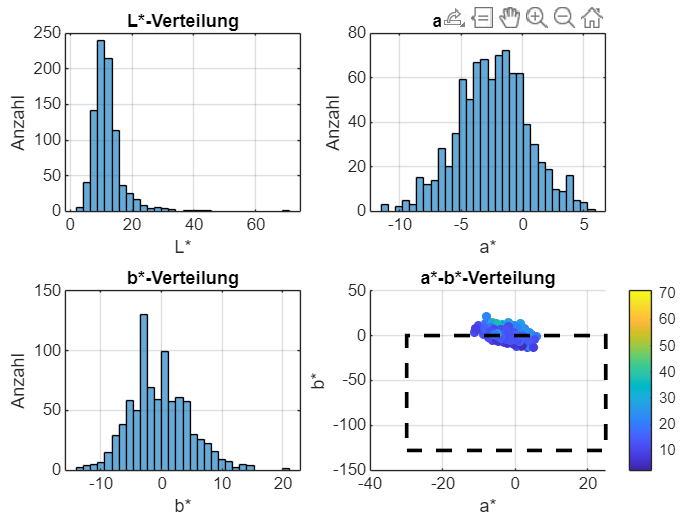



%% 8. Gesamtergebnisse speichern

if isempty(allResults)

    warning("Es wurden keine Pixel ausgewählt.");

else

    writetable( ...
        allResults, ...
        outputCsv);

    fprintf("\n============================================\n");
    fprintf("Analyse abgeschlossen\n");
    fprintf("============================================\n");

    fprintf("Gespeicherte Einzelpixel: %d\n", height(allResults));

    fprintf("Ergebnisdatei:\n%s\n", outputCsv);


    %% Gesamtauswertung aller Problembilder

    allLabValues = [
        allResults.L_Wert, ...
        allResults.A_Wert, ...
        allResults.B_Wert
    ];

    percentileValues = [2; 5; 50; 95; 98];

    totalPercentiles = prctile( ...
        allLabValues, ...
        percentileValues, ...
        1);

    totalPercentileTable = table( ...
        percentileValues, ...
        totalPercentiles(:,1), ...
        totalPercentiles(:,2), ...
        totalPercentiles(:,3), ...
        'VariableNames', ...
        {'Perzentil', 'L_Wert', 'A_Wert', 'B_Wert'});

    fprintf("\nPerzentile aller angeklickten Problempixel:\n");
    disp(totalPercentileTable);


    fprintf( ...
        "L*-Bedingung insgesamt erfüllt: %.1f %%\n", ...
        100 * mean(allResults.L_Bedingung));

    fprintf( ...
        "a*-Bedingung insgesamt erfüllt: %.1f %%\n", ...
        100 * mean(allResults.A_Bedingung));

    fprintf( ...
        "b*-Bedingung insgesamt erfüllt: %.1f %%\n", ...
        100 * mean(allResults.B_Bedingung));

    fprintf( ...
        "Alle Bedingungen insgesamt erfüllt: %.1f %%\n", ...
        100 * mean(allResults.Gesamtbedingung));


    %% Gesamte Verteilung darstellen

    figure( ...
        "Name", "Gesamtauswertung der Problembilder", ...
        "NumberTitle", "off");

    tiledlayout( ...
        2, 2, ...
        "TileSpacing", "compact", ...
        "Padding", "compact");


    nexttile;

    histogram( ...
        allResults.L_Wert, ...
        30);

    xlabel("L*");
    ylabel("Anzahl");
    title("L*-Verteilung");
    grid on;


    nexttile;

    histogram( ...
        allResults.A_Wert, ...
        30);

    xlabel("a*");
    ylabel("Anzahl");
    title("a*-Verteilung");
    grid on;


    nexttile;

    histogram( ...
        allResults.B_Wert, ...
        30);

    xlabel("b*");
    ylabel("Anzahl");
    title("b*-Verteilung");
    grid on;


    nexttile;

    scatter( ...
        allResults.A_Wert, ...
        allResults.B_Wert, ...
        25, ...
        allResults.L_Wert, ...
        "filled");

    hold on;

    rectangle( ...
        "Position", ...
        [ ...
            Amin, ...
            Bmin, ...
            Amax - Amin, ...
            Bmax - Bmin ...
        ], ...
        "LineWidth", 2, ...
        "LineStyle", "--");

    xlabel("a*");
    ylabel("b*");

    title("a*-b*-Verteilung");
    colorbar;
    grid on;

    hold off;

end